full_lnp = importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\full_lnp_sol.mat');
empty_lnp =importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\empty_lnp_sol.mat');
blebbed_lnp = importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\blebbed_lnp_sol.mat');

%% ========================================================================
%  Solve BEM for LNP populations against a real glass/water substrate,
%  following the documented +optics workflow (Hitzelhammer et al.,
%  "Unified Simulation Platform for Interference Microscopy", ACS
%  Photonics SI, demoiscat01.m pattern).
%  ========================================================================

%% ---- wavelength (match your laser / filter) ----
lambda = 555;              % nm
k0 = 2 * pi / lambda;

%% ---- substrate: glass coverslip below, aqueous buffer above (z=0 interface) ----
% NOTE: this water index must match whatever the LNP meshes were built
% against (n_medium = 1.335 in lnp_populations_nanobem.m) -- the layer's
% upper medium and the particle's "outside" material need to agree
% physically even though they're separate Material objects here.
n_glass = 1.515;           % check against your actual coverslip glass
n_water = 1.335;
mat_glass = Material(n_glass^2, 1);
mat_water = Material(n_water^2, 1);
layer = stratified.layerstructure([mat_glass, mat_water], 0);

%% ---- illumination: match your actual microscope geometry ----
% pol = polarization, dir = propagation direction. dir=[0,0,1] illuminates
% from below (through the glass, upward into the water/particle side),
% the standard inverted-microscope epi-iSCAT geometry. For oblique/
% off-axis illumination, tilt dir; for a transmissive COBRI setup,
% illumination instead comes from the water side (dir=[0,0,-1]) with the
% detection lens on the glass side.
pol = [1, 0, 0];
dir = [0, 0, 1];
einc = optics.decompose(k0, pol, dir);

%% -------------------------------------------------------------------------
%  1. Solve single-boundary populations (empty_lnp and full_lnp)
% -------------------------------------------------------------------------
single_pops = {'empty_lnp', 'full_lnp'};

for p = 1:numel(single_pops)
    pop_name = single_pops{p};
    pop_data = eval(pop_name);
    fprintf('Solving BEM for %s...\n', pop_name);
    for i = 1:numel(pop_data)
        tau  = pop_data{i}.tau;
        qinc = einc(tau, 'layer', layer);              % inhomogeneities incl. secondary fields
        bem  = stratified.bemsolver(tau, layer, 'order', []);
        pop_data{i}.sol = bem \ qinc;
    end
    assignin('caller', pop_name, pop_data);
end

Solving BEM for empty_lnp...


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


Solving BEM for full_lnp...


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 284] rad2=[1 284]


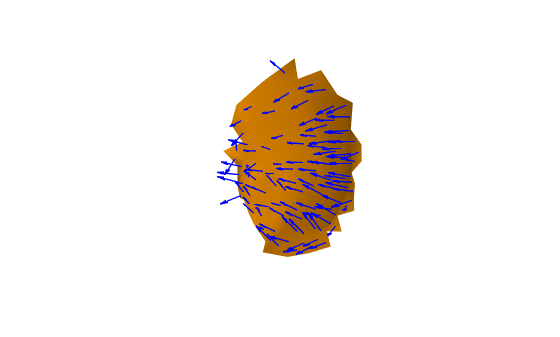

figure; plot(blebbed_lnp{1}.tau_interface, 'nvec', true);


% -------------------------------------------------------------------------
%  2. Solve multi-boundary population (blebbed_lnp)
% -------------------------------------------------------------------------
fprintf('Solving BEM for blebbed_lnp...\n');

Solving BEM for blebbed_lnp...


for i = 1:numel(blebbed_lnp)
    % All THREE boundaries -- exterior lipid, exterior aqueous, AND the
    % internal lipid/aqueous interface -- are required to close the
    % multi-region system.
    tau = [blebbed_lnp{i}.tau_lipid_out, ...
       blebbed_lnp{i}.tau_aqueous_out, ...
       blebbed_lnp{i}.tau_interface];

    qinc = einc(tau, 'layer', layer);
    bem = stratified.bemsolver(tau, layer, 'order', 5);

    blebbed_lnp{i}.tau = tau;
    blebbed_lnp{i}.sol = bem \ qinc;
end

DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 275] rad2=[1 275]
DEBUG rad1=[1 275] rad2=[1 273]
DEBUG rad1=[1 273] rad2=[1 275]
DEBUG rad1=[1 273] rad2=[1 273]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 415] rad2=[1 415]
DEBUG rad1=[1 415] rad2=[1 289]
DEBUG rad1=[1 289] rad2=[1 415]
DEBUG rad1=[1 289] rad2=[1 289]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 495] rad2=[1 495]
DEBUG rad1=[1 495] rad2=[1 209]
DEBUG rad1=[1 209] rad2=[1 495]
DEBUG rad1=[1 209] rad2=[1 209]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 889] rad2=[1 889]
DEBUG rad1=[1 889] rad2=[1 287]
DEBUG rad1=[1 287] rad2=[1 889]
DEBUG rad1=[1 287] rad2=[1 287]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 452] rad2=[1 452]
DEBUG rad1=[1 452] rad2=[1 328]
DEBUG rad1=[1 328] rad2=[1 452]
DEBUG rad1=[1 328] rad2=[1 328]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 560] rad2=[1 560]
DEBUG rad1=[1 560] rad2=[1 264]
DEBUG rad1=[1 264] rad2=[1 560]
DEBUG rad1=[1 264] rad2=[1 264]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 232] rad2=[1 232]
DEBUG rad1=[1 232] rad2=[1 318]
DEBUG rad1=[1 318] rad2=[1 232]
DEBUG rad1=[1 318] rad2=[1 318]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 198] rad2=[1 198]
DEBUG rad1=[1 198] rad2=[1 270]
DEBUG rad1=[1 270] rad2=[1 198]
DEBUG rad1=[1 270] rad2=[1 270]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 620] rad2=[1 620]
DEBUG rad1=[1 620] rad2=[1 242]
DEBUG rad1=[1 242] rad2=[1 620]
DEBUG rad1=[1 242] rad2=[1 242]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 416] rad2=[1 416]
DEBUG rad1=[1 416] rad2=[1 196]
DEBUG rad1=[1 196] rad2=[1 416]
DEBUG rad1=[1 196] rad2=[1 196]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 287] rad2=[1 287]
DEBUG rad1=[1 287] rad2=[1 211]
DEBUG rad1=[1 211] rad2=[1 287]
DEBUG rad1=[1 211] rad2=[1 211]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 418] rad2=[1 418]
DEBUG rad1=[1 418] rad2=[1 224]
DEBUG rad1=[1 224] rad2=[1 418]
DEBUG rad1=[1 224] rad2=[1 224]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 745] rad2=[1 745]
DEBUG rad1=[1 745] rad2=[1 247]
DEBUG rad1=[1 247] rad2=[1 745]
DEBUG rad1=[1 247] rad2=[1 247]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 391] rad2=[1 391]
DEBUG rad1=[1 391] rad2=[1 237]
DEBUG rad1=[1 237] rad2=[1 391]
DEBUG rad1=[1 237] rad2=[1 237]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 423] rad2=[1 423]
DEBUG rad1=[1 423] rad2=[1 163]
DEBUG rad1=[1 163] rad2=[1 423]
DEBUG rad1=[1 163] rad2=[1 163]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 425] rad2=[1 425]
DEBUG rad1=[1 425] rad2=[1 277]
DEBUG rad1=[1 277] rad2=[1 425]
DEBUG rad1=[1 277] rad2=[1 277]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 200] rad2=[1 200]
DEBUG rad1=[1 200] rad2=[1 374]
DEBUG rad1=[1 374] rad2=[1 200]
DEBUG rad1=[1 374] rad2=[1 374]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 244] rad2=[1 244]
DEBUG rad1=[1 244] rad2=[1 334]
DEBUG rad1=[1 334] rad2=[1 244]
DEBUG rad1=[1 334] rad2=[1 334]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


DEBUG rad1=[1 574] rad2=[1 574]
DEBUG rad1=[1 574] rad2=[1 212]
DEBUG rad1=[1 212] rad2=[1 574]
DEBUG rad1=[1 212] rad2=[1 212]


DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]
DEBUG it=2 class(obj.mat)=Material numel(obj.mat)=2 size(obj.mat(it))=[1 1]


%% ========================================================================

Best volume-matched triplet found:


  empty_lnp{16}:   volume=295395 nm^3  (eq. diameter 82.6 nm)


  full_lnp{10}:    volume=293330 nm^3  (eq. diameter 82.4 nm)


  blebbed_lnp{9}: volume=294221 nm^3  (eq. diameter 82.5 nm)


  spread (max-min volume): 2064 nm^3 (24.7% of the target volume)


Unrecognized function or variable 'render_iscat_image'.

%  Propagate solved BEM fields to simulated camera images, matching the
%  real microscope: Nikon Ti2 inverted scope, 100x plan apochromat (NA
%  1.45) + 1.5x built-in intermediate magnification, Prime95B camera
%  (Photometrics), epi-illumination via Lumencor Spectra through a
%  fixed-FOV fly-eye-homogenized illuminator (Ti2-LAPP).
%  Run this after solve_lnp_populations.m.
%  ========================================================================
 
%% ---- objective + magnification ----
NA = 1.45;                      % 100x plan apochromat (lambda series), NA 1.45
mag_objective    = 100;
mag_intermediate = 1.5;         % Ti2 built-in intermediate magnification lens
mag_total = mag_objective * mag_intermediate;   % 150x
 
%% ---- camera: Prime95B, full-frame FOV/pixel count given directly ----
% 118x118 um FOV over a 1608x1608 sensor -- this figure already reflects
% the full 150x system magnification, so the effective pixel size
% referred back to the SAMPLE plane comes directly from it (118000 nm /
% 1608 px), no separate magnification arithmetic needed.
sensor_fov_um = 118;
sensor_pixels = 1608;
pixel_size_nm = sensor_fov_um * 1000 / sensor_pixels;   % ~73.38 nm/pixel at the sample
 
% Experiments used a reduced 1200x1200 pixel ROI (~88x88 um at the
% sample) for focus stability across the field. Simulating a full
% 1200x1200 Richards-Wolf image PER PARTICLE (1.44M points, times every
% particle in every population) isn't computationally realistic here.
% Instead: same physically-correct pixel pitch, much smaller window
% centered on each particle -- a single particle's iSCAT PSF only
% extends a couple um, so this is ample headroom. Bump npix up toward
% roi_pixels_full if you have the compute budget and want to compare
% against a real full-ROI crop.
roi_pixels_full = 1200;   %#ok<NASGU> documented experimental ROI, for reference
npix = 61;                 % simulated window size per particle (odd, centered)
icenter = ceil(npix / 2);  % index of the central (y=0) row for line profiles
 
x = pixel_size_nm * ( -(npix-1)/2 : (npix-1)/2 );   % nm, centered on the particle
 
% NOTE: nanobem's optics.lensimage has no magnification parameter -- it
% computes the Richards-Wolf image in object-space-referred coordinates
% for the given (mat1, mat2, NA). Using the real camera pixel size
% divided by total system magnification (already folded into the
% 118um/1608px figure above) is the standard way to reconcile that, but
% I haven't independently verified this convention against nanobem's
% source -- check demooptics02.m / demoiscat02.m if you want to confirm
% before trusting absolute numbers.
 
%% ---- illumination geometry ----
% Epi-illumination via a fixed large-FOV illuminator with a built-in
% fly-eye lens (Ti2-LAPP) is specifically designed to Kohler-homogenize
% the beam into flat, uniform illumination across the FOV -- consistent
% with the normal-incidence plane wave already used for `einc` in
% solve_lnp_populations.m. No focused-beam (optics.lensfocus) treatment
% needed for this illumination path.
%
% Not specified in the given description: illumination polarization
% (Spectra + fly-eye epi illumination is typically effectively
% unpolarized, whereas `einc` here assumes a single linear polarization)
% and which specific wavelength/filter channel was used for the data
% you're comparing against -- lambda is still whatever was set in
% solve_lnp_populations.m (555 nm), update it there if your acquisition
% used a different channel.
 
%% ---- object-side / image-side media for the imaging lens ----
% Object side: what the objective optically looks through -- glass
% substrate. Oil-immersion objectives are index-matched close to glass,
% so mat_glass is the standard simplification, same as the SI's own
% NA=1.3 example (no separate oil term there either).
% Image side: air, between the tube lens and the camera sensor. This is
% NOT where immersion oil belongs.
air = Material(1, 1);
rot = optics.roty(180);   % epi-detection through the same objective, see prior notes
lens = optics.lensimage(mat_glass, air, k0, NA, 'rot', rot);
 
% Reference field: reflection of the incoming excitation at the
% substrate interface, propagating back down toward the objective --
% this IS the iSCAT reference wave, computed from the physical substrate
% reflection rather than added by hand.
refl = secondary(einc, layer, 'dir', 'down');

%% ========================================================================
%  Find the empty/full/blebbed LNP triplet with the most closely matched
%  volume, so any visual difference in their iSCAT images can be
%  attributed to shape/material rather than confounded by particle size.
%  Run after solve_lnp_populations.m (needs .sol on every particle).
%  ========================================================================

%% ---- volume of each particle in each population ----
sphere_vol = @(d) (4/3) * pi * (d/2).^3;

vol_full  = cellfun(@(pp) sphere_vol(pp.diameter), full_lnp);
vol_empty = cellfun(@(pp) sphere_vol(pp.diameter), empty_lnp);

% Blebbed: union volume of two intersecting spheres, NOT the naive sum
% (which would double-count the overlapping lens-shaped region).
% Standard sphere-sphere intersection volume formula (Wolfram MathWorld):
%   V_overlap = (pi/(12*d)) * (r1+r2-d)^2 * (d^2 + 2*d*(r1+r2) - 3*(r1-r2)^2)
% where d = center-to-center distance. Since center_dist was built as
% r1+r2-neck_overlap, (r1+r2-d) here is exactly neck_overlap.
bleb_union_vol = @(pp) local_bleb_volume(pp.d_core, pp.d_bleb, pp.neck_overlap);
vol_bleb = cellfun(bleb_union_vol, blebbed_lnp);

%% ---- sweep candidate target volumes, find best-matched triplet ----
% Candidates: every volume actually present in any of the three groups --
% the optimal "join point" will always be at (or very near) one of these,
% so this is effectively exhaustive without being combinatorial.
candidates = unique([vol_full(:); vol_empty(:); vol_bleb(:)]);

best_spread = Inf;
best_idx = [NaN, NaN, NaN];   % [i_empty, i_full, i_bleb]

for k = 1:numel(candidates)
    v = candidates(k);
    [~, i_full]  = min(abs(vol_full  - v));
    [~, i_empty] = min(abs(vol_empty - v));
    [~, i_bleb]  = min(abs(vol_bleb  - v));

    matched = [vol_empty(i_empty), vol_full(i_full), vol_bleb(i_bleb)];
    spread = max(matched) - min(matched);   % simple range; could use std instead

    if spread < best_spread
        best_spread = spread;
        best_idx = [i_empty, i_full, i_bleb];
    end
end

[i_empty, i_full, i_bleb] = deal(best_idx(1), best_idx(2), best_idx(3));

d_eq = @(V) (6*V/pi)^(1/3);   % equivalent-sphere diameter, for readability

fprintf('Best volume-matched triplet found:\n');
fprintf('  empty_lnp{%d}:   volume=%.0f nm^3  (eq. diameter %.1f nm)\n', ...
    i_empty, vol_empty(i_empty), d_eq(vol_empty(i_empty)));
fprintf('  full_lnp{%d}:    volume=%.0f nm^3  (eq. diameter %.1f nm)\n', ...
    i_full, vol_full(i_full), d_eq(vol_full(i_full)));
fprintf('  blebbed_lnp{%d}: volume=%.0f nm^3  (eq. diameter %.1f nm)\n', ...
    i_bleb, vol_bleb(i_bleb), d_eq(vol_bleb(i_bleb)));
fprintf('  spread (max-min volume): %.0f nm^3 (%.1f%% of the target volume)\n', ...
    best_spread, 100*best_spread/candidates(1));

%% ---- render the matched triplet, each at its OWN best focus ----
% Reuses render_iscat_zscan / render_iscat_image / lens / refl / x /
% z_scan / icenter from simulate_iscat_images.m -- run that first (both
% the single-focus AND defocus-scan setup sections) so those exist in
% the workspace.
%
% NOTE: this recomputes best_z specifically for i_empty/i_full/i_bleb
% (the actual matched particles found above), rather than reusing the
% population-level `best_z` struct from simulate_iscat_images.m -- that
% struct was calibrated on whichever particle `particle_idx` pointed to
% there, which is very likely a DIFFERENT specific particle than the ones
% matched here by volume. Since defocus optimum can genuinely shift with
% particle size/orientation, using each matched particle's own
% best-focus is the more defensible choice for isolating "differences
% due to geometry/material" as cleanly as possible -- but it also means
% the three panels may end up at three DIFFERENT z values, not one
% shared focus. That's noted in each title below rather than hidden.
labels_base = { sprintf('empty (d_{eq}=%.0f nm)',   d_eq(vol_empty(i_empty))), ...
                sprintf('full (d_{eq}=%.0f nm)',    d_eq(vol_full(i_full))), ...
                sprintf('blebbed (d_{eq}=%.0f nm)', d_eq(vol_bleb(i_bleb))) };
sols_matched = { empty_lnp{i_empty}.sol, full_lnp{i_full}.sol, blebbed_lnp{i_bleb}.sol };

contrasts_matched = cell(3, 1);
xz_matched         = cell(3, 1);   % z-by-x contrast profile for each matched particle
titles_matched    = cell(3, 1);
for p = 1:3
    [xz_matched{p}, best_z_p] = render_iscat_zscan(sols_matched{p}, lens, refl, x, z_scan, icenter);
    focus_p = [0, 0, best_z_p];
    [~, contrasts_matched{p}] = render_iscat_image(sols_matched{p}, lens, refl, x, focus_p);
    titles_matched{p} = sprintf('%s, z=%.0f nm', labels_base{p}, best_z_p);
    fprintf('  %s: best focus z = %g nm\n', labels_base{p}, best_z_p);
end

cmax_matched = max(cellfun(@(c) max(abs(c(:))), contrasts_matched));
clims_matched = [-cmax_matched, cmax_matched];

figure;
for p = 1:3
    ax = subplot(1, 3, p);
    imagesc(ax, x, x, contrasts_matched{p}, clims_matched); axis(ax, 'image'); colorbar(ax);
    colormap(ax, 'gray');
    title(ax, titles_matched{p});
end
sgtitle(sprintf('Volume-matched triplet (spread: %.1f%% of target)', 100*best_spread/candidates(1)));

%% ---- z-by-x defocus profile for each matched particle ----
% Same shared-color-scale logic as the single-focus figure above, applied
% across the three z-by-x maps so they're fairly comparable to each other
% too, not just auto-scaled independently.
cmax_zx = max(cellfun(@(c) max(abs(c(:))), xz_matched));
clims_zx = [-cmax_zx, cmax_zx];

figure;
for p = 1:3
    ax = subplot(1, 3, p);
    imagesc(ax, x, z_scan, xz_matched{p}, clims_zx); axis(ax, 'xy'); colorbar(ax);
    colormap(ax, 'gray');
    xlabel(ax, 'x (nm)'); ylabel(ax, 'z focus (nm)');
    title(ax, labels_base{p});
end
sgtitle('Volume-matched triplet: z-by-x contrast profiles (defocus scan)');

%% ---- local function: union volume of two intersecting spheres ----
function V = local_bleb_volume(d_core, d_bleb, neck_overlap)
    r1 = d_core / 2;
    r2 = d_bleb / 2;
    d  = r1 + r2 - neck_overlap;   % center-to-center distance

    V1 = (4/3) * pi * r1^3;
    V2 = (4/3) * pi * r2^3;

    if d >= r1 + r2
        V_overlap = 0;   % spheres don't actually touch
    elseif d <= abs(r1 - r2)
        V_overlap = (4/3) * pi * min(r1, r2)^3;   % one fully contains the other
    else
        V_overlap = (pi / (12*d)) * (r1 + r2 - d)^2 * ...
            (d^2 + 2*d*(r1 + r2) - 3*(r1 - r2)^2);
    end

    V = V1 + V2 - V_overlap;
end

%% ========================================================================
%  Propagate solved BEM fields to simulated camera images, matching the
%  real microscope: Nikon Ti2 inverted scope, 100x plan apochromat (NA
%  1.45) + 1.5x built-in intermediate magnification, Prime95B camera
%  (Photometrics), epi-illumination via Lumencor Spectra through a
%  fixed-FOV fly-eye-homogenized illuminator (Ti2-LAPP).
%  Run this after solve_lnp_populations.m.
%  ========================================================================

%% ---- objective + magnification ----
NA = 1.45;                      % 100x plan apochromat (lambda series), NA 1.45
mag_objective    = 100;
mag_intermediate = 1.5;         % Ti2 built-in intermediate magnification lens
mag_total = mag_objective * mag_intermediate;   % 150x

%% ---- camera: Prime95B, full-frame FOV/pixel count given directly ----
% 118x118 um FOV over a 1608x1608 sensor -- this figure already reflects
% the full 150x system magnification, so the effective pixel size
% referred back to the SAMPLE plane comes directly from it (118000 nm /
% 1608 px), no separate magnification arithmetic needed.
sensor_fov_um = 118;
sensor_pixels = 1608;
pixel_size_nm = sensor_fov_um * 1000 / sensor_pixels;   % ~73.38 nm/pixel at the sample

% Experiments used a reduced 1200x1200 pixel ROI (~88x88 um at the
% sample) for focus stability across the field. Simulating a full
% 1200x1200 Richards-Wolf image PER PARTICLE (1.44M points, times every
% particle in every population) isn't computationally realistic here.
% Instead: same physically-correct pixel pitch, much smaller window
% centered on each particle -- a single particle's iSCAT PSF only
% extends a couple um, so this is ample headroom. Bump npix up toward
% roi_pixels_full if you have the compute budget and want to compare
% against a real full-ROI crop.
roi_pixels_full = 1200;   %#ok<NASGU> documented experimental ROI, for reference
npix = 61;                 % simulated window size per particle (odd, centered)
icenter = ceil(npix / 2);  % index of the central (y=0) row for line profiles

x = pixel_size_nm * ( -(npix-1)/2 : (npix-1)/2 );   % nm, centered on the particle

% NOTE: nanobem's optics.lensimage has no magnification parameter -- it
% computes the Richards-Wolf image in object-space-referred coordinates
% for the given (mat1, mat2, NA). Using the real camera pixel size
% divided by total system magnification (already folded into the
% 118um/1608px figure above) is the standard way to reconcile that, but
% I haven't independently verified this convention against nanobem's
% source -- check demooptics02.m / demoiscat02.m if you want to confirm
% before trusting absolute numbers.

%% ---- illumination geometry ----
% Epi-illumination via a fixed large-FOV illuminator with a built-in
% fly-eye lens (Ti2-LAPP) is specifically designed to Kohler-homogenize
% the beam into flat, uniform illumination across the FOV -- consistent
% with the normal-incidence plane wave already used for `einc` in
% solve_lnp_populations.m. No focused-beam (optics.lensfocus) treatment
% needed for this illumination path.
%
% Not specified in the given description: illumination polarization
% (Spectra + fly-eye epi illumination is typically effectively
% unpolarized, whereas `einc` here assumes a single linear polarization)
% and which specific wavelength/filter channel was used for the data
% you're comparing against -- lambda is still whatever was set in
% solve_lnp_populations.m (555 nm), update it there if your acquisition
% used a different channel.

%% ---- object-side / image-side media for the imaging lens ----
% Object side: what the objective optically looks through -- glass
% substrate. Oil-immersion objectives are index-matched close to glass,
% so mat_glass is the standard simplification, same as the SI's own
% NA=1.3 example (no separate oil term there either).
% Image side: air, between the tube lens and the camera sensor. This is
% NOT where immersion oil belongs.
air = Material(1, 1);
rot = optics.roty(180);   % epi-detection through the same objective, see prior notes
lens = optics.lensimage(mat_glass, air, k0, NA, 'rot', rot);

% Reference field: reflection of the incoming excitation at the
% substrate interface, propagating back down toward the objective --
% this IS the iSCAT reference wave, computed from the physical substrate
% reflection rather than added by hand.
refl = secondary(einc, layer, 'dir', 'down');

%% ---- helper: single-focus iSCAT image from a solved boundary+solution ----
function [im, contrast, ibg] = render_iscat_image(sol, lens, refl, x, focus)
    far  = farfields(sol, lens.dir);
    isca = efield(lens, far,  x, x, 'focus', focus);
    iref = efield(lens, refl, x, x, 'focus', focus);
    isca = flip(isca, 1);   % flip x-axis, consequence of the rot=180 lens axis
    iref = flip(iref, 1);

    im  = dot(isca + iref, isca + iref, 3);   % total interference intensity
    ibg = dot(iref, iref, 3);                  % reference-only (background) intensity
    contrast = (im - ibg) ./ ibg * 100;        % iSCAT contrast, percent
end

%% ---- helper: defocus (z) scan -- central x-line contrast at each z ----
function [xz_contrast, best_z, xz_ibg, xz_numerator] = render_iscat_zscan(sol, lens, refl, x, z_scan, icenter)
    far = farfields(sol, lens.dir);   % computed ONCE -- doesn't depend on focus
    xz_contrast   = zeros(numel(z_scan), numel(x));
    xz_ibg        = zeros(numel(z_scan), numel(x));
    xz_numerator  = zeros(numel(z_scan), numel(x));
    for iz = 1:numel(z_scan)
        focus = [0, 0, z_scan(iz)];
        isca = efield(lens, far,  x, x, 'focus', focus);
        iref = efield(lens, refl, x, x, 'focus', focus);
        isca = flip(isca, 1);
        iref = flip(iref, 1);
        im  = dot(isca + iref, isca + iref, 3);
        ibg = dot(iref, iref, 3);
        contrast = (im - ibg) ./ ibg * 100;
        xz_contrast(iz, :)  = contrast(icenter, :);
        xz_ibg(iz, :)       = ibg(icenter, :);          % NOTE: identical for
                                                          % every particle at a
                                                          % given z_scan/x/focus
                                                          % -- doesn't depend on sol
        xz_numerator(iz, :) = im(icenter, :) - ibg(icenter, :);   % raw interference
                                                                    % signal, NOT
                                                                    % divided by ibg --
                                                                    % a fairer strength
                                                                    % comparison across
                                                                    % particles
    end
    % Focal plane where the RAW interference signal (numerator) peaks,
    % EXCLUDING any z where ibg has collapsed below a floor -- maximizing
    % the numerator alone isn't sufficient (see discussion): near true
    % focus, a particle's strongest scattered signal and the reference
    % beam's own weakest on-axis intensity (a real Gouy-phase-related
    % effect for tightly focused high-NA beams, not a bug) can genuinely
    % coincide in z, and dividing a large numerator by a collapsed ibg
    % still gives an enormous, physically-meaningless-in-practice
    % contrast. A z where ibg is a small fraction of its typical value in
    % this scan is a low-photon-count, shot-noise-dominated regime no
    % real experimentalist would want to measure at regardless of how
    % large the nominal signal looks -- so exclude those z first, then
    % pick whichever survivor maximizes the raw numerator.
    ibg_floor_frac = 0.1;   % exclude z where ibg < 10% of its own scan max; tune if needed
    ibg_ok = xz_ibg(:, icenter) >= ibg_floor_frac * max(xz_ibg(:, icenter));

    numerator_masked = abs(xz_numerator(:, icenter));
    numerator_masked(~ibg_ok) = -Inf;

    if all(~ibg_ok)
        warning('render_iscat_zscan:allExcluded', ...
            'Every z in this scan has ibg below the floor -- widen z_scan or lower ibg_floor_frac.');
        numerator_masked = abs(xz_numerator(:, icenter));   % fall back to unmasked rather than error
    end

    [~, idx_best] = max(numerator_masked);
    best_z = z_scan(idx_best);
end

%% ---- defocus (z) scan: volume-matched particle from each population ----
% Running this on all 20 particles per population would be slow given
% everything we've hit with this pipeline so far -- one representative
% particle each, extend the loop to more particles once you've confirmed
% runtime is acceptable.
%
% IMPORTANT: previously this used the SAME fixed index across all three
% populations -- but that's not a meaningful match, since a given index
% in blebbed_lnp has no relationship to that same index in full_lnp
% (independently, randomly generated populations). Any visual difference
% between panels could just as easily reflect a size mismatch as a
% genuine shape/material difference. Instead, find genuinely
% volume-matched particles (same approach as find_matched_volume_triplet.m,
% sharing bleb_volume.m so this can't drift out of sync with that script)
% and use THOSE same particles consistently in both sections below.
pops = {'empty_lnp', 'full_lnp', 'blebbed_lnp'};

sphere_vol = @(d) (4/3) * pi * (d/2).^3;
vol_full  = cellfun(@(pp) sphere_vol(pp.diameter), full_lnp);
vol_empty = cellfun(@(pp) sphere_vol(pp.diameter), empty_lnp);
vol_bleb  = cellfun(@(pp) bleb_volume(pp.d_core, pp.d_bleb, pp.neck_overlap), blebbed_lnp);

candidates = unique([vol_full(:); vol_empty(:); vol_bleb(:)]);
best_spread = Inf;
best_idx = [NaN, NaN, NaN];   % [i_empty, i_full, i_bleb]
for k = 1:numel(candidates)
    v = candidates(k);
    [~, i_full]  = min(abs(vol_full  - v));
    [~, i_empty] = min(abs(vol_empty - v));
    [~, i_bleb]  = min(abs(vol_bleb  - v));
    matched = [vol_empty(i_empty), vol_full(i_full), vol_bleb(i_bleb)];
    spread = max(matched) - min(matched);
    if spread < best_spread
        best_spread = spread;
        best_idx = [i_empty, i_full, i_bleb];
    end
end

% Same particle index used everywhere below, per population -- this is
% what "the same LNPs for best_z and the x-by-z profile" actually means.
idx = struct('empty_lnp', best_idx(1), 'full_lnp', best_idx(2), 'blebbed_lnp', best_idx(3));
fprintf('Volume-matched particles selected (spread: %.1f%% of target volume):\n', ...
    100*best_spread/candidates(1));

Volume-matched particles selected (spread: 24.7% of target volume):


fprintf('  empty_lnp{%d}, full_lnp{%d}, blebbed_lnp{%d}\n', idx.empty_lnp, idx.full_lnp, idx.blebbed_lnp);

  empty_lnp{16}, full_lnp{10}, blebbed_lnp{9}



z_scan = -2000:20:2000;   % nm -- starting range, widen/narrow once you see
                          % where the peak actually falls

xz = struct();
best_z = struct();
for p = 1:numel(pops)
    pop_name = pops{p};
    pop_data = eval(pop_name);
    fprintf('Running z-scan for %s (particle %d)...\n', pop_name, idx.(pop_name));
    [xz.(pop_name), best_z.(pop_name)] = ...
        render_iscat_zscan(pop_data{idx.(pop_name)}.sol, lens, refl, x, z_scan, icenter);
    fprintf('  best focus (peak raw interference signal at particle center): z = %g nm\n', best_z.(pop_name));
end

Running z-scan for empty_lnp (particle 16)...


  best focus (peak raw interference signal at particle center): z = 100 nm


Running z-scan for full_lnp (particle 10)...


  best focus (peak raw interference signal at particle center): z = 100 nm


Running z-scan for blebbed_lnp (particle 9)...


  best focus (peak raw interference signal at particle center): z = 20 nm


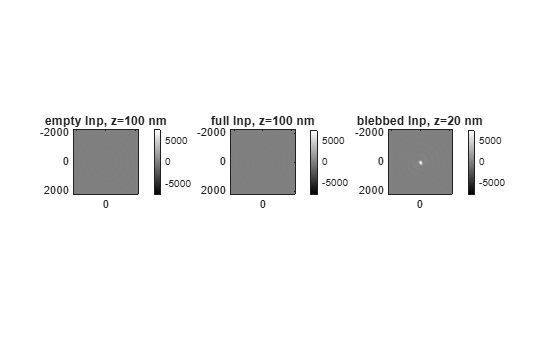


%% ---- single-focus quick look, AT EACH POPULATION'S CALIBRATED best_z ----
% Same volume-matched particles (idx.(pop_name)) as the z-scan above, so
% these two sections are always looking at the same physical particles.
% Plain linear scale, no cube-root compression -- unlike the earlier
% placeholder-focus version, this now images each population at its own
% best_z (computed just above, using the raw-numerator selection that
% avoids the ibg-null bias), so there's much less risk of an extreme
% outlier pixel needing to be compressed away in the first place.
contrasts = cell(numel(pops), 1);
for p = 1:numel(pops)
    pop_data = eval(pops{p});
    focus_p = [0, 0, best_z.(pops{p})];
    [~, contrasts{p}] = render_iscat_image(pop_data{idx.(pops{p})}.sol, lens, refl, x, focus_p);
end

% Symmetric around zero, since contrast is signed (constructive vs.
% destructive interference) -- this keeps "no signal" at a consistent
% gray level and equal-magnitude +/- contrast at equal-magnitude
% brightness deviations across all three panels.
cmax = max(cellfun(@(c) max(abs(c(:))), contrasts));
clims = [-cmax, cmax];

figure;
for p = 1:numel(pops)
    pop_name = pops{p};
    ax = subplot(1, 3, p);
    imagesc(ax, x, x, contrasts{p}, clims); axis(ax, 'image'); colorbar(ax);
    colormap(ax, 'gray');   % set PER AXES -- a trailing colormap(gca,...)
                             % after all three subplots only ever affected
                             % the last one, which was a real bug
    title(ax, sprintf('%s, z=%.0f nm', strrep(pop_name, '_', ' '), best_z.(pop_name)));
end

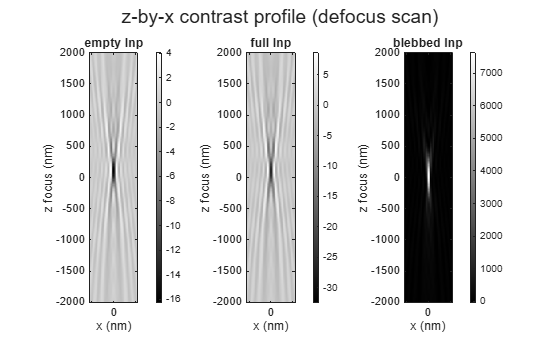


% z-by-x contrast maps, one per population
figure;
for p = 1:numel(pops)
    pop_name = pops{p};
    ax = subplot(1, 3, p);
    imagesc(ax, x, z_scan, xz.(pop_name)); axis(ax, 'xy'); colorbar(ax);
    colormap(ax, 'gray');
    xlabel(ax, 'x (nm)'); ylabel(ax, 'z focus (nm)');
    title(ax, strrep(pop_name, '_', ' '));
end
sgtitle('z-by-x contrast profile (defocus scan)');

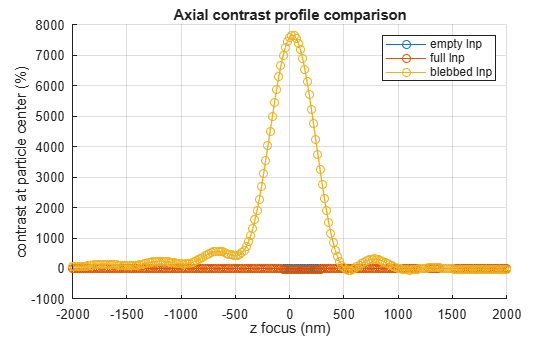


% axial contrast profile comparison: particle-center contrast vs z,
% overlaid across populations
figure;
hold on;
colors = lines(numel(pops));   % line colors only -- image colormaps above
                                 % stay grayscale, this is just for the
                                 % overlay plot's line distinguishability
for p = 1:numel(pops)
    pop_name = pops{p};
    plot(z_scan, xz.(pop_name)(:, icenter), '-o', 'Color', colors(p,:), ...
        'DisplayName', strrep(pop_name, '_', ' '));
end
xlabel('z focus (nm)'); ylabel('contrast at particle center (%)');
title('Axial contrast profile comparison');
legend('show'); grid on;


%% ========================================================================
%  Per-particle defocus scan for EVERY blebbed LNP, labeled by orientation
%  ========================================================================
% NOTE: this runs the (relatively expensive) far-field + z-scan pipeline
% once per blebbed particle -- for N_bleb=20 that's 20x the work of the
% single-representative-particle version above. Worth checking runtime on
% a handful first if you have many particles.
n_bleb = numel(blebbed_lnp);

xz_bleb     = struct();
best_z_bleb = struct();
labels_bleb = cell(n_bleb, 1);

for p = 1:n_bleb
    particle = blebbed_lnp{p};
    key = sprintf('p%02d', p);   % valid struct fieldname; azimuth/tilt go in the label instead

    fprintf('Running z-scan for blebbed particle %d/%d (azimuth=%.0f deg, tilt=%.0f deg)...\n', ...
        p, n_bleb, particle.phi_azimuth_deg, particle.theta_tilt_deg);

    [xz_bleb.(key), best_z_bleb.(key)] = ...
        render_iscat_zscan(particle.sol, lens, refl, x, z_scan, icenter);

    fprintf('  best focus (peak |contrast| at particle center): z = %g nm\n', best_z_bleb.(key));

    labels_bleb{p} = sprintf('#%d, az=%.0f%s, tilt=%.0f%s', ...
        p, particle.phi_azimuth_deg, char(176), particle.theta_tilt_deg, char(176));
end

Running z-scan for blebbed particle 1/20 (azimuth=307 deg, tilt=83 deg)...


  best focus (peak |contrast| at particle center): z = 180 nm


Running z-scan for blebbed particle 2/20 (azimuth=64 deg, tilt=153 deg)...


  best focus (peak |contrast| at particle center): z = 180 nm


Running z-scan for blebbed particle 3/20 (azimuth=43 deg, tilt=37 deg)...


  best focus (peak |contrast| at particle center): z = -200 nm


Running z-scan for blebbed particle 4/20 (azimuth=360 deg, tilt=66 deg)...


  best focus (peak |contrast| at particle center): z = 220 nm


Running z-scan for blebbed particle 5/20 (azimuth=275 deg, tilt=94 deg)...


  best focus (peak |contrast| at particle center): z = 200 nm


Running z-scan for blebbed particle 6/20 (azimuth=129 deg, tilt=130 deg)...


  best focus (peak |contrast| at particle center): z = 160 nm


Running z-scan for blebbed particle 7/20 (azimuth=63 deg, tilt=109 deg)...


  best focus (peak |contrast| at particle center): z = -200 nm


Running z-scan for blebbed particle 8/20 (azimuth=169 deg, tilt=69 deg)...


  best focus (peak |contrast| at particle center): z = 200 nm


Running z-scan for blebbed particle 9/20 (azimuth=265 deg, tilt=61 deg)...


  best focus (peak |contrast| at particle center): z = 20 nm


Running z-scan for blebbed particle 10/20 (azimuth=108 deg, tilt=79 deg)...


  best focus (peak |contrast| at particle center): z = -80 nm


Running z-scan for blebbed particle 11/20 (azimuth=26 deg, tilt=38 deg)...


  best focus (peak |contrast| at particle center): z = 120 nm


Running z-scan for blebbed particle 12/20 (azimuth=5 deg, tilt=97 deg)...


  best focus (peak |contrast| at particle center): z = -20 nm


Running z-scan for blebbed particle 13/20 (azimuth=111 deg, tilt=144 deg)...


  best focus (peak |contrast| at particle center): z = -100 nm


Running z-scan for blebbed particle 14/20 (azimuth=120 deg, tilt=8 deg)...


  best focus (peak |contrast| at particle center): z = 160 nm


Running z-scan for blebbed particle 15/20 (azimuth=17 deg, tilt=114 deg)...


  best focus (peak |contrast| at particle center): z = 240 nm


Running z-scan for blebbed particle 16/20 (azimuth=32 deg, tilt=75 deg)...


  best focus (peak |contrast| at particle center): z = 120 nm


Running z-scan for blebbed particle 17/20 (azimuth=192 deg, tilt=36 deg)...


  best focus (peak |contrast| at particle center): z = 200 nm


Running z-scan for blebbed particle 18/20 (azimuth=106 deg, tilt=109 deg)...


  best focus (peak |contrast| at particle center): z = 180 nm


Running z-scan for blebbed particle 19/20 (azimuth=240 deg, tilt=155 deg)...


  best focus (peak |contrast| at particle center): z = 180 nm


Running z-scan for blebbed particle 20/20 (azimuth=255 deg, tilt=63 deg)...


  best focus (peak |contrast| at particle center): z = 60 nm


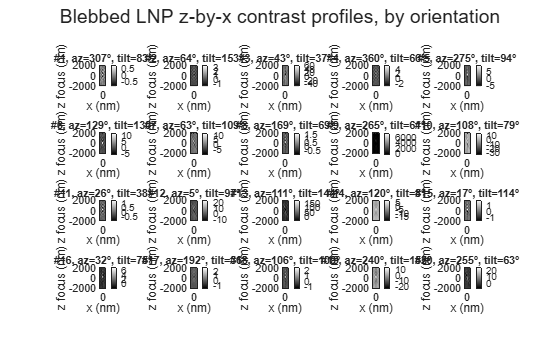


% z-by-x contrast maps, one subplot per blebbed particle
ncols = ceil(sqrt(n_bleb));
nrows = ceil(n_bleb / ncols);

figure;
for p = 1:n_bleb
    key = sprintf('p%02d', p);
    ax = subplot(nrows, ncols, p);
    imagesc(ax, x, z_scan, xz_bleb.(key)); axis(ax, 'xy'); colorbar(ax);
    colormap(ax, 'gray');
    xlabel(ax, 'x (nm)'); ylabel(ax, 'z focus (nm)');
    title(ax, labels_bleb{p}, 'FontSize', 8);
end
sgtitle('Blebbed LNP z-by-x contrast profiles, by orientation');

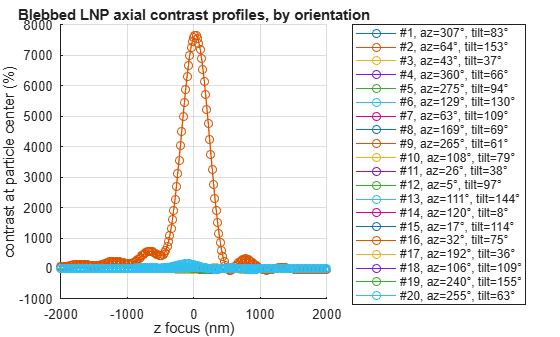


% axial contrast profile comparison across all blebbed particles,
% overlaid and colored/labeled by azimuth angle
figure;
hold on;
colors_bleb = lines(n_bleb);
for p = 1:n_bleb
    key = sprintf('p%02d', p);
    plot(z_scan, xz_bleb.(key)(:, icenter), '-o', 'Color', colors_bleb(p,:), ...
        'DisplayName', labels_bleb{p});
end
xlabel('z focus (nm)'); ylabel('contrast at particle center (%)');
title('Blebbed LNP axial contrast profiles, by orientation');
legend('show', 'Location', 'eastoutside'); grid on;

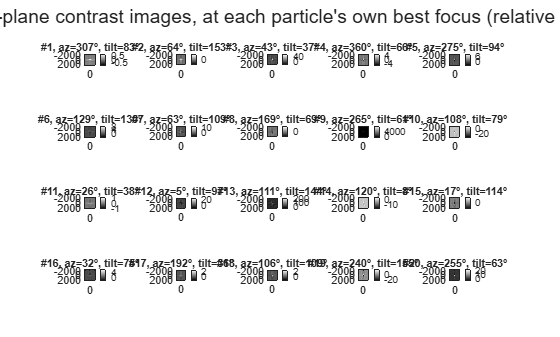


%% ---- per-particle single-focus (x-by-y) images, at each particle's own best_z ----
% Same particles/labels as the z-by-x grid above, now showing the actual
% in-plane image at each particle's own calibrated focus rather than the
% defocus sweep. NOTE: this recomputes farfields(sol, lens.dir) again for
% each particle -- render_iscat_zscan just did the same computation
% internally for the z-scan above, so this doubles the far-field
% evaluations for the whole population. Same redundancy already exists
% elsewhere in this project; worth fixing later if runtime becomes an
% issue, not addressed here to keep this consistent with the rest of the
% pipeline for now.
contrasts_bleb = struct();
for p = 1:n_bleb
    key = sprintf('p%02d', p);
    particle = blebbed_lnp{p};
    focus_p = [0, 0, best_z_bleb.(key)];
    [~, contrasts_bleb.(key)] = render_iscat_image(particle.sol, lens, refl, x, focus_p);
end

% RELATIVE scale per panel -- no shared clims this time, unlike every
% other multi-panel figure in this project. Each imagesc auto-scales to
% its own data range, so every particle's own structure is visible
% regardless of its absolute contrast magnitude. Trade-off: brightness is
% no longer comparable ACROSS panels -- a "bright" pixel in one particle's
% image and a "bright" pixel in another's could correspond to very
% different actual contrast percentages. Read the colorbar numbers, not
% the visual intensity, if you need to compare magnitude between particles.
figure;
for p = 1:n_bleb
    key = sprintf('p%02d', p);
    ax = subplot(nrows, ncols, p);
    imagesc(ax, x, x, contrasts_bleb.(key)); axis(ax, 'image'); colorbar(ax);
    colormap(ax, 'gray');
    title(ax, labels_bleb{p}, 'FontSize', 8);
end
sgtitle('Blebbed LNP in-plane contrast images, at each particle''s own best focus (relative scale per panel)');